# Demo:  Rate Distributions with Small and Large-Scale Fading

In this short demo, we show how to make simple predictions of rate CDFs with both small-scale and large-scale fading.

## Large-Scale Model

As a simple example, suppose that the SNR at a distance `d`  is given by:

where `d0 = 100` meters is  a reference distance and `gam0 = 10 dB`.  Assume users are distributed with the distance, d uniformly from `[50, 200]` m.  The distance `d` would be considered a **large-scale** parameter, since it does not vary within a coding block.  To get an idea of the distribution over the SNRs due to large-scale variations, we draw  1000 random users, and plot the CDF of the average SNR

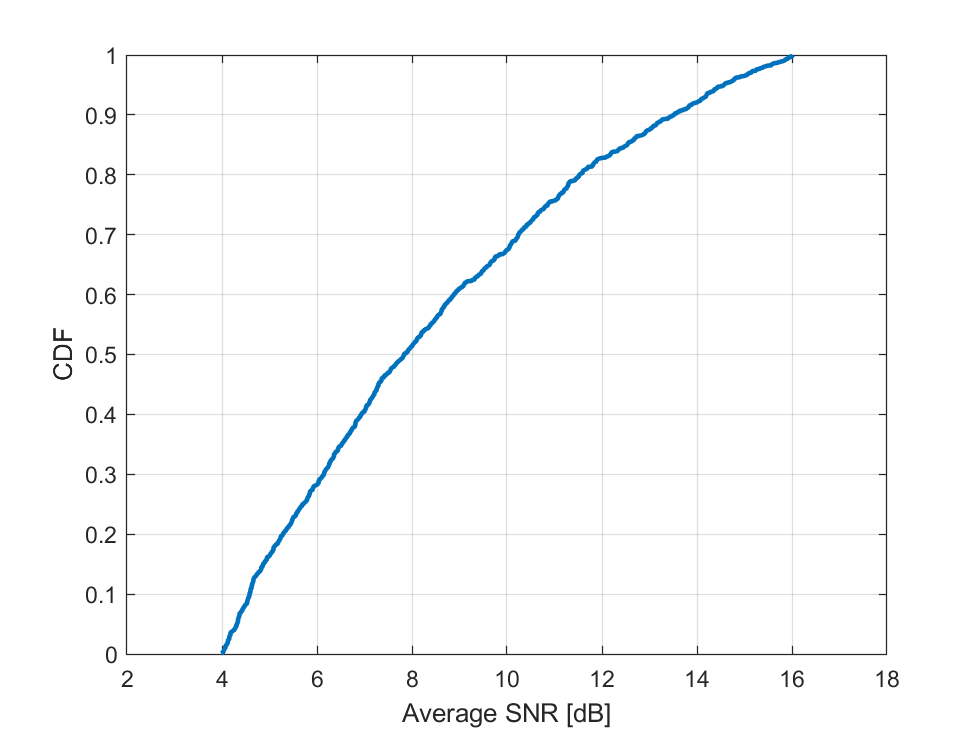

npts = 1000;                  % number of points
d = unifrnd(50,200,npts,1);   % random distances
d0 = 100;   % Reference distance
gam0 = 10;  % Reference SNR in dB

% Compute average SNR in each location
gam0Lin = db2pow(gam0);
snrAvgLin = gam0Lin*(d0./d).^2;
snrAvg = pow2db(snrAvgLin);

% Plot the SNR CDF
plot(sort(snrAvg), (1:npts)/npts, '-', 'LineWidth', 2);
grid on;
xlabel('Average SNR [dB]');
ylabel('CDF');

## SNR Distribution with Flat and Slow Fading

Now suppose that there is Rayleigh fading at each location.  Suppose each user transmits one packet and the packet experiences flat and slow fading (i.e. a constant SNR that is Rayleigh distributed around its average).  We can plot the CDF of the SNR experienced by the packets as follows.  We see there is a high degree of variability due to the small scale fading.

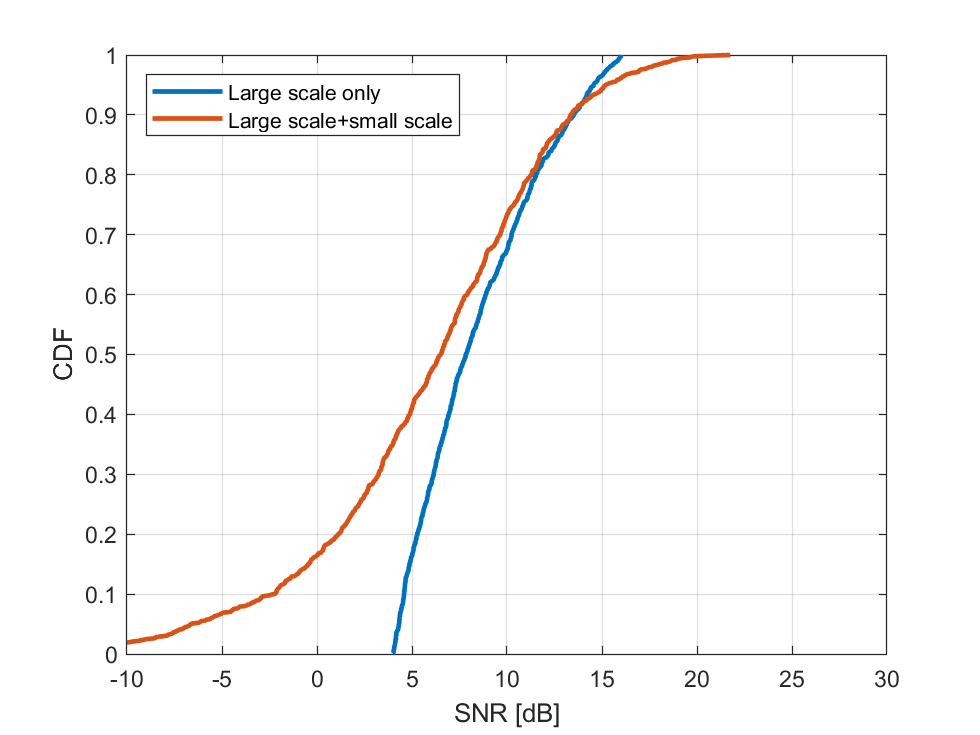

% Compute the SNR with small-scale fading by adding an exponential random
% variable to the average SNR:
mu = 1;
snrLin = snrAvgLin.*exprnd(mu, npts, 1);
snr = pow2db(snrLin);

% Plot the SNR CDF
plot(sort(snrAvg), (1:npts)/npts, '-', 'LineWidth', 2);
hold on;
plot(sort(snr), (1:npts)/npts, '-', 'LineWidth', 2);
grid on;
hold off;
xlabel('SNR [dB]');
ylabel('CDF');
legend('Large scale only', 'Large scale+small scale', 'Location', 'Northwest');
xlim([-10,30]);

Again under the assumption that each packet experiences flat and slow fading, draw the CDF of the Shannon spectral efficiency (=capacity / degree of freedom) in each packet?

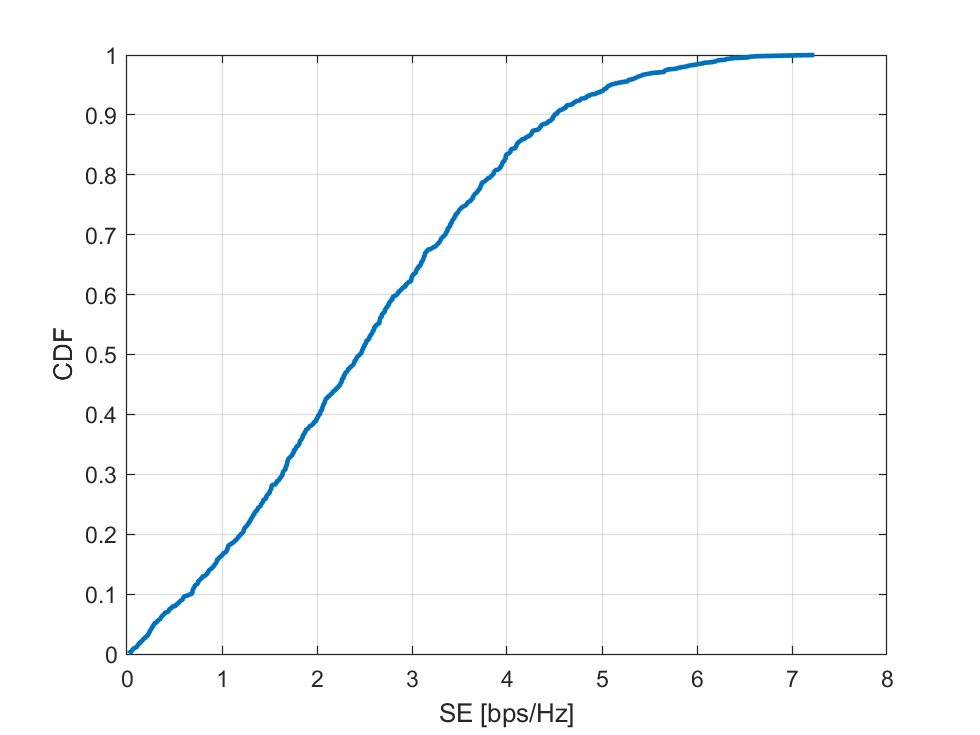

% SE of each packet under shannon model
seConst = log2(1 + snrLin);

% Plot the CDF
plot(sort(seConst), (1:npts)/npts, '-', 'LineWidth', 2);
hold off;
xlabel('SE [bps/Hz]');
ylabel('CDF');
grid on;

## Rate Distribution under IID Small-Scale Fading Model

Now suppose that you can code over either a very large BW or long time so each packets experiences the Ergodic capacity for the average SNR.  In this case, we can compute the ergodic capacity / degree of freedom as follows:

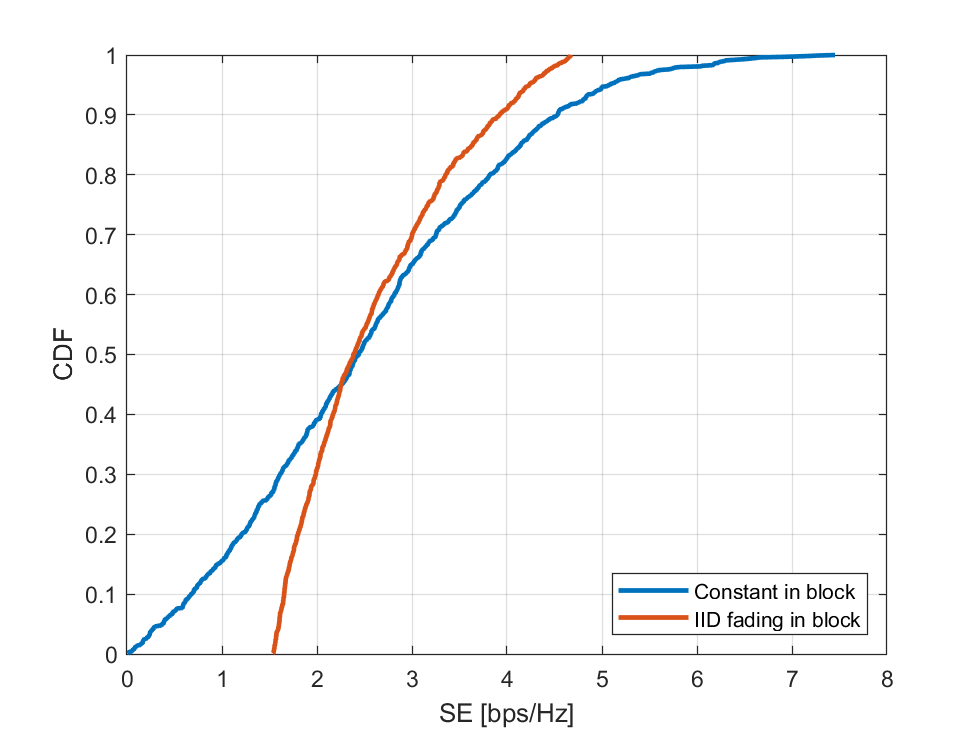

% For each location, generate nfade random fades
nfade = 1000;
u = exprnd(1, 1, nfade);

% Create a matrix snrFade(i,j) = SNR on location i with fade j
snrFade = snrAvgLin*u;  

% Average over the fading realizations at each location
seIID = mean(log2(1 + snrFade), 2);

% Plot the rate CDFs
plot(sort(seConst), (1:npts)/npts, '-', 'LineWidth', 2);
hold on;
plot(sort(seIID), (1:npts)/npts, '-', 'LineWidth', 2);
hold off;
xlabel('SE [bps/Hz]');
ylabel('CDF');
legend('Constant in block', 'IID fading in block', 'Location', 'Southeast');
grid on;